# PATIPPET simulations for manuscript

© Jonathan Cannon, MIT, 2020

## Tempo estimation

PATIPPET initially expects a range of tempi centered on 1. But in a few clicks, it recognizes the real tempo and develops a high degree of confidence in its estimate.

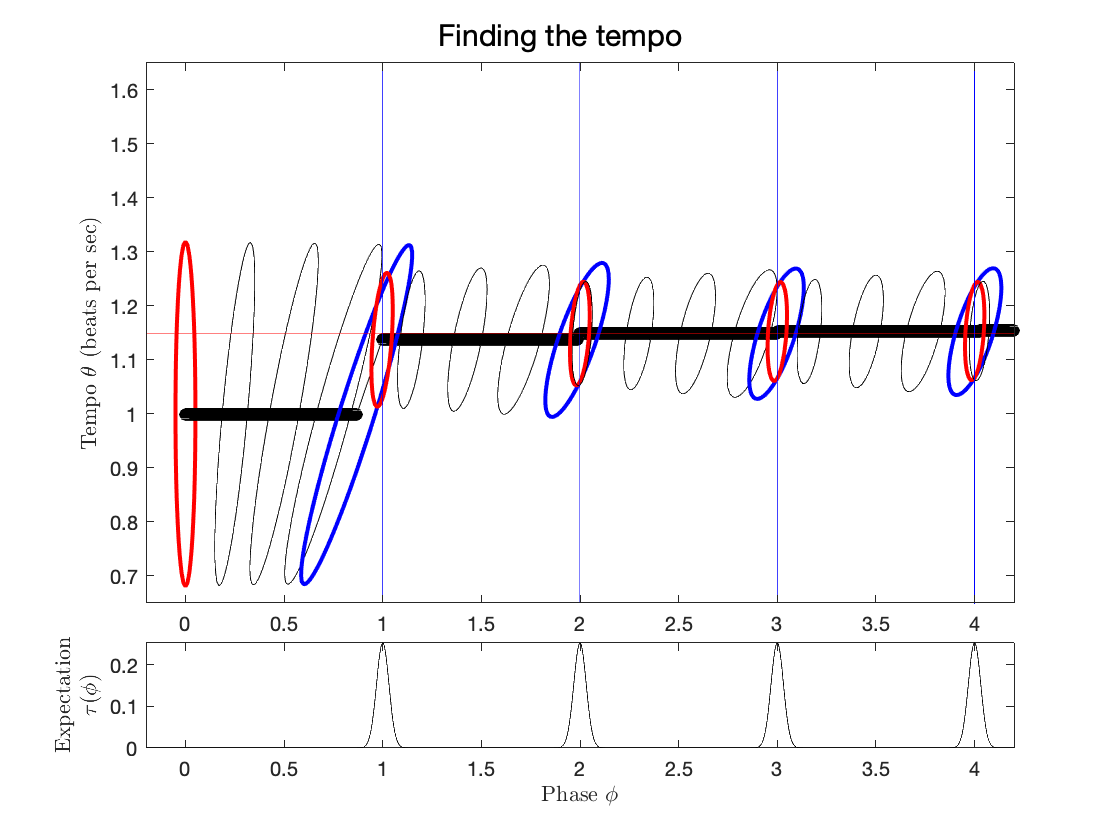

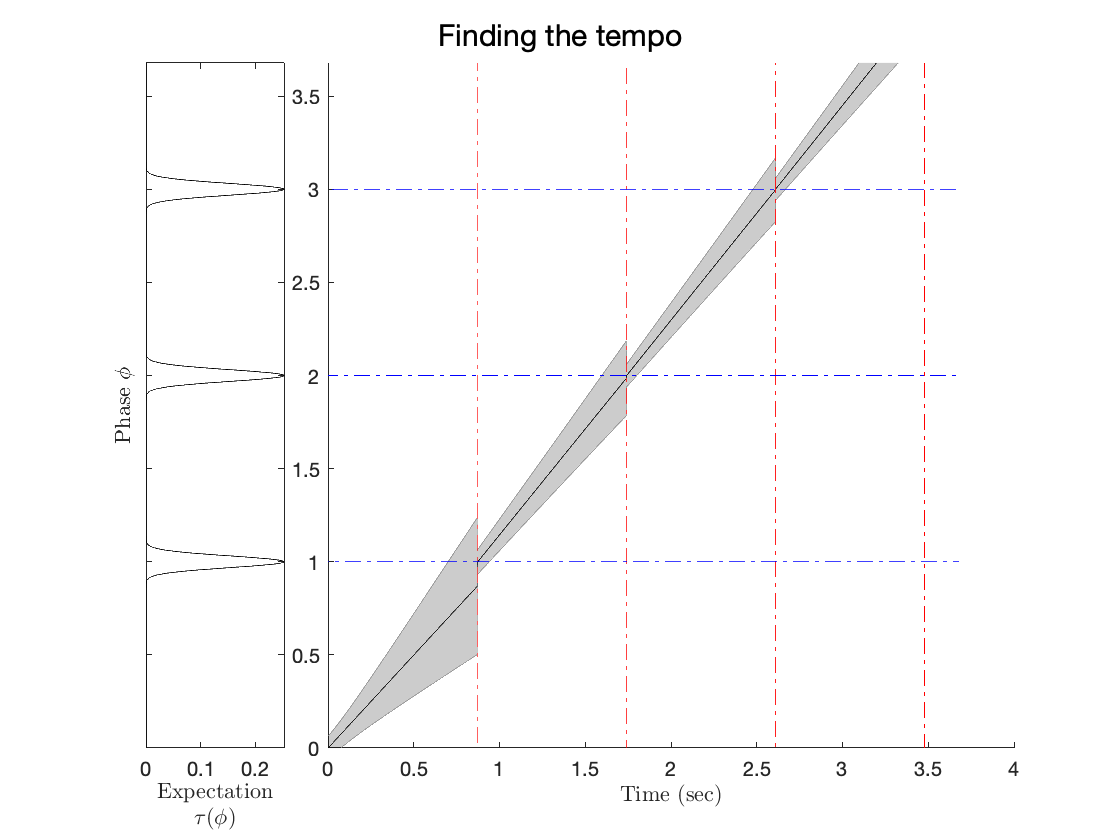

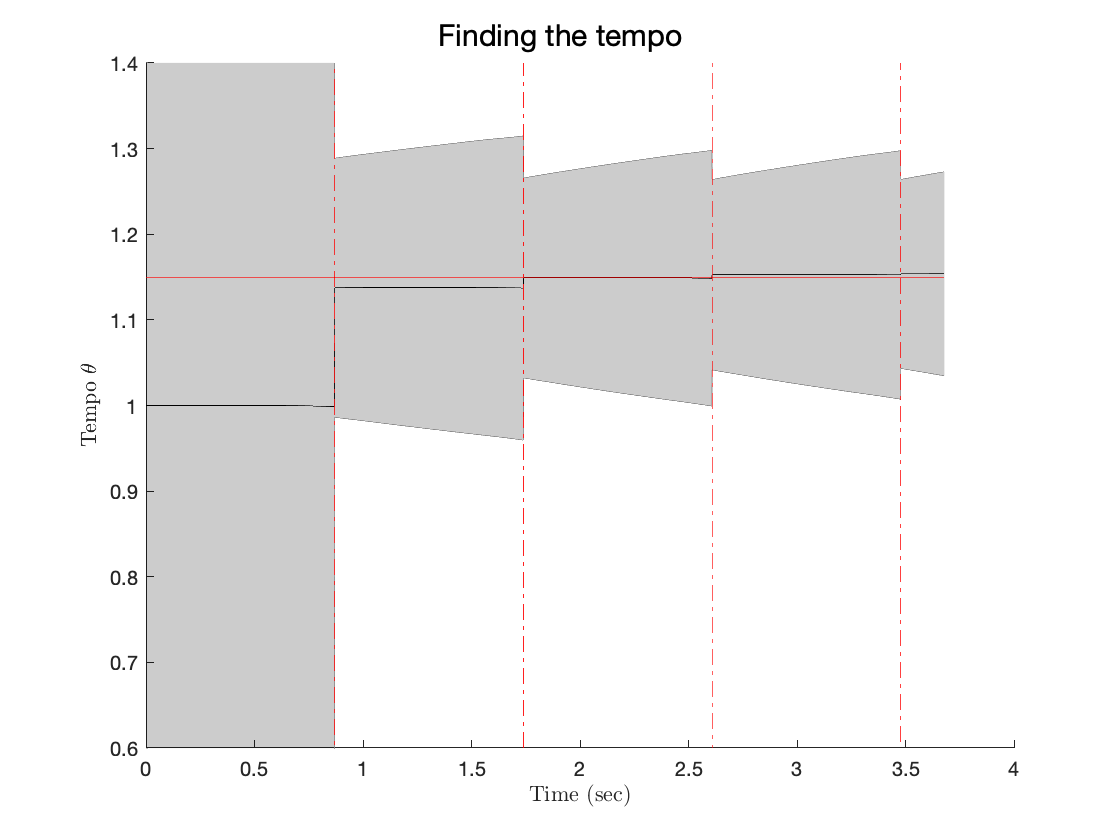


true_tempo = 1.15;
period = 1/true_tempo;

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, 1],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Finding the tempo', ...
    'display_phase', true, ...
    'display_tempo', true);
[xbar_list, Sigma_list] = run_PATIPPET(params);

## Phase shift as a function of tempo

PATIPPET is given time to entrain to four different tempi, and then given a phase shifted click. Taps are assumed to happen each time the mean estimated phase reaches an integer, except at the phase shift, which is assumed to take place too close to a tap for that tap to adjust. Tap times are used to 

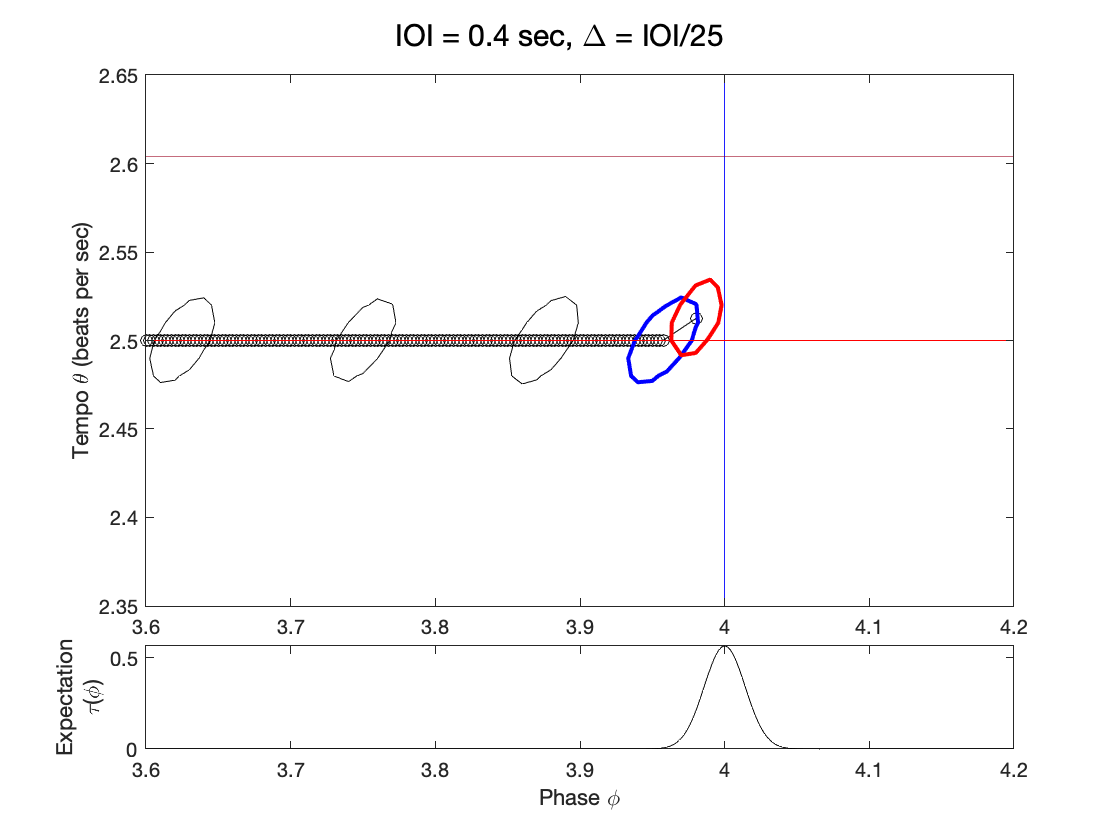

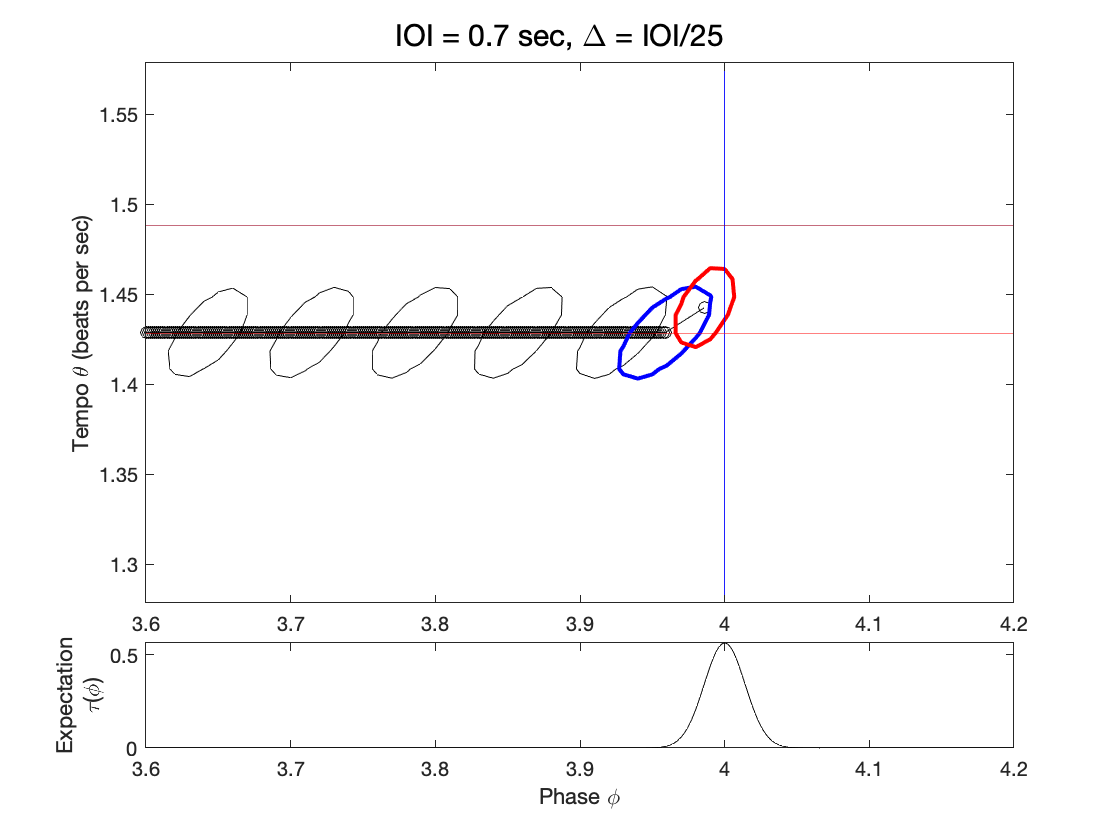

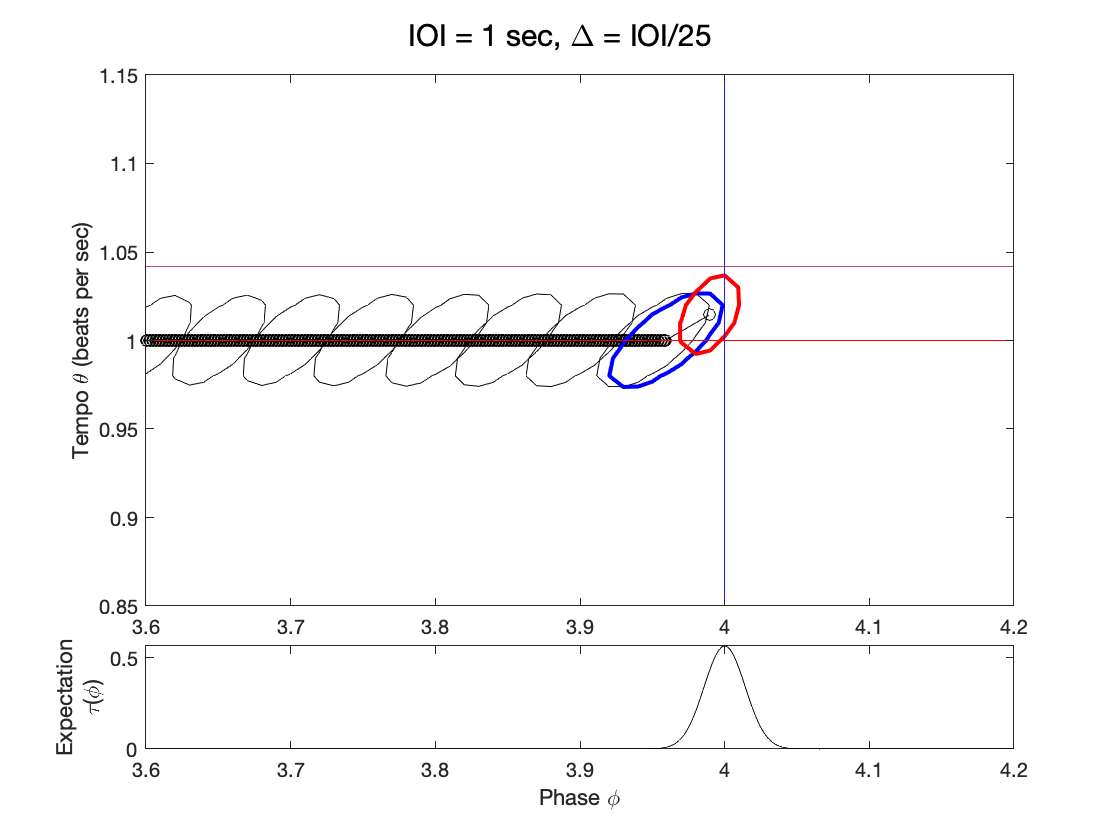

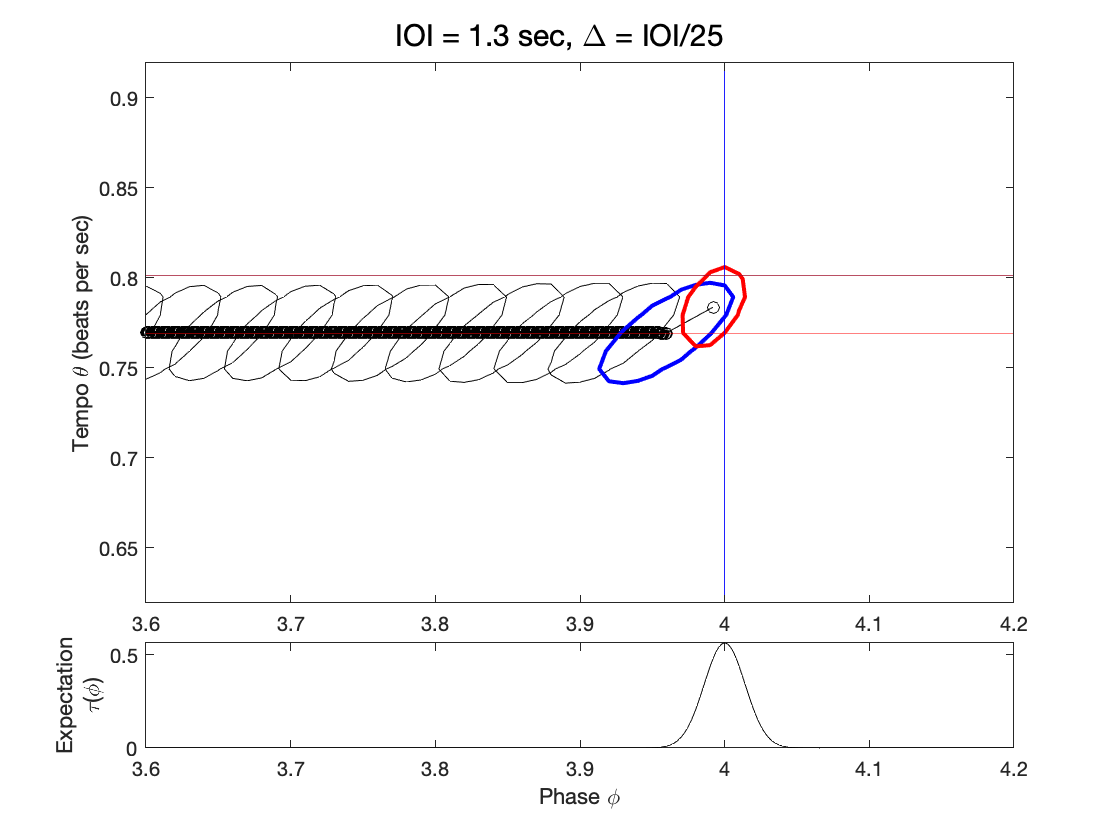


dt = .001;

params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit', [.0002],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'sigma_phi', 0.01,...
    'sigma_theta', 0.01,...
    'tau_0', .00001,...
    'Sigma_0', [.0001, 0; 0, .0001],...
    'dt_ellipse', .05,...
    'display_phasetempo', true);

period_list = [.4, .7, 1, 1.3];

%%% Any of the following phase shift schemes give similar results.

%delta_list = -period_list.^2 / 20; % phase shifts corresponding to equal tempo changes
%delta_string = "\Delta = IOI^2 / 20";
delta_list = -period_list / 25; % phase shifts proportional to period
delta_string = "\Delta = IOI/25";
%delta_list = -.01*ones(size(period_list)); % identical phase shifts
%delta_string = "\Delta = 0.01 sec";


xbar_final_list = zeros(2, length(period_list));
xbar_initial_list = zeros(2, length(period_list));
Sigma_final_list = zeros(2,2, length(period_list));
Sigma_initial_list = zeros(2,2, length(period_list));

for i = 1:length(period_list)
    params.streams{1}.event_times = [period_list(i), 2*period_list(i), 3*period_list(i), 4*period_list(i)+delta_list(i)];
    params.tmax = 4*period_list(i)+delta_list(i);
    params.true_speed = 1/period_list(i);
    params.xbar_0 = [0, 1/period_list(i)];
    params.title = "IOI = " + num2str(period_list(i))+ " sec, "+delta_string; % Correct title if using different
    
    [xbar_list, Sigma_list] = run_PATIPPET(params);
    ylim([1/period_list(i) - .15, 1/period_list(i)+.15])
    xlim([3.6, 4.2])
    plot([3.6, 4.2], [1,1]*(1./(period_list(i)+delta_list(i))));
    subplot(5,1,5)
    xlim([3.6, 4.2])
    xbar_final_list(:, i) = xbar_list(:, end);
    xbar_initial_list(:, i) = xbar_list(:, end-1);
    Sigma_final_list(:,:, i) = Sigma_list(:, :,end);
    Sigma_initial_list(:,:, i) = Sigma_list(:, :,end-1);
    
    
end


fourth_tap_times = 4*period_list;

phase_until_next_tap = 5 - xbar_final_list(1,:);

time_until_next_tap = phase_until_next_tap./xbar_final_list(2,:);

fifth_tap_times = fourth_tap_times + delta_list + time_until_next_tap;

next_asynchrony = (5*period_list + delta_list) - fifth_tap_times;

alpha_list = (delta_list-next_asynchrony)./delta_list;

figure()
hold on
plot(period_list, -(xbar_final_list(1,:)-xbar_initial_list(1,:))./(delta_list/period_list), 'o-')
plot(period_list, (xbar_final_list(2,:) - xbar_initial_list(2,:))./(1./(period_list + delta_list) - 1./period_list), 'o-')
%plot(period_list, xbar_initial_list(1,:), 'o-')
ylabel('Fraction corrected')
xlabel('Inter-onset interval (sec)')
lgd = legend('Phase (\bar{\phi})', 'Tempo (\bar{\theta})');
lgd.Location = 'northwest'

lgd =   Legend (Phase (\bar{\phi}), Tempo (\bar{\theta})) with properties:

         String: {'Phase (\bar{\phi})'  'Tempo (\bar{\theta})'}
       Location: 'northwest'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.1446 0.8429 0.2179 0.0631]
          Units: 'normalized'

  Show all properties


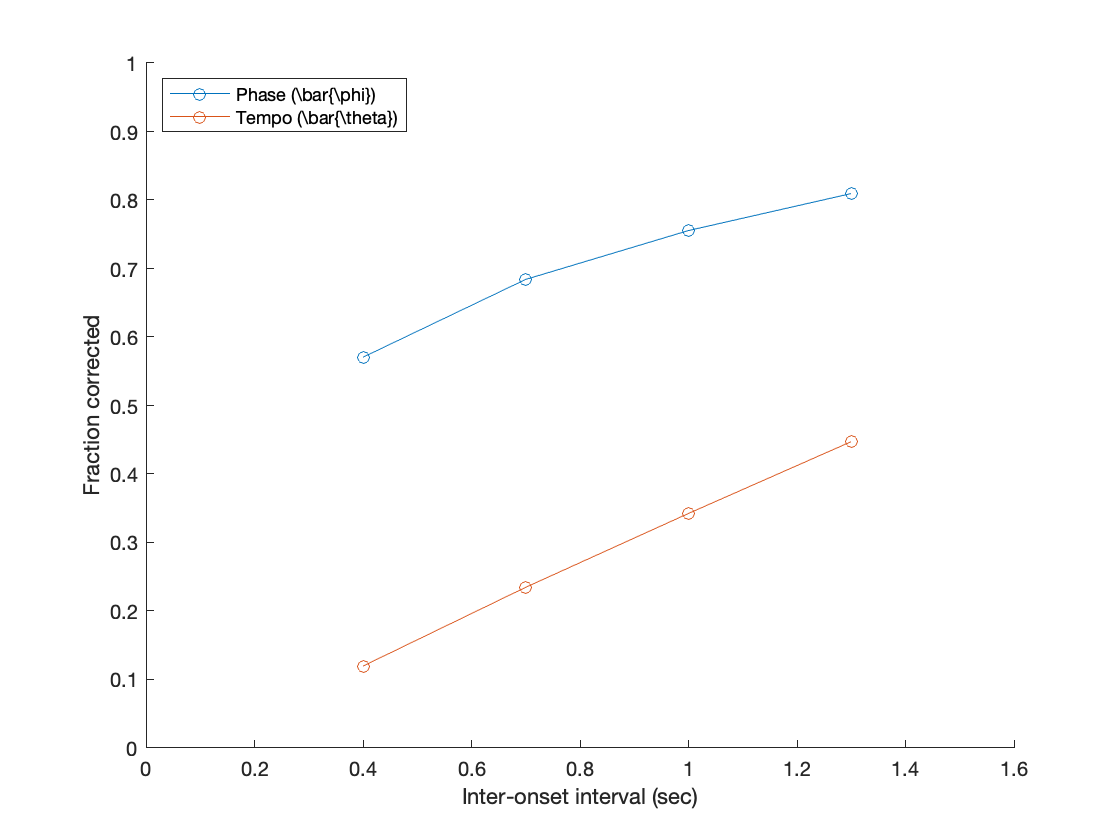

xlim([0, 1.6])
ylim([0, 1])

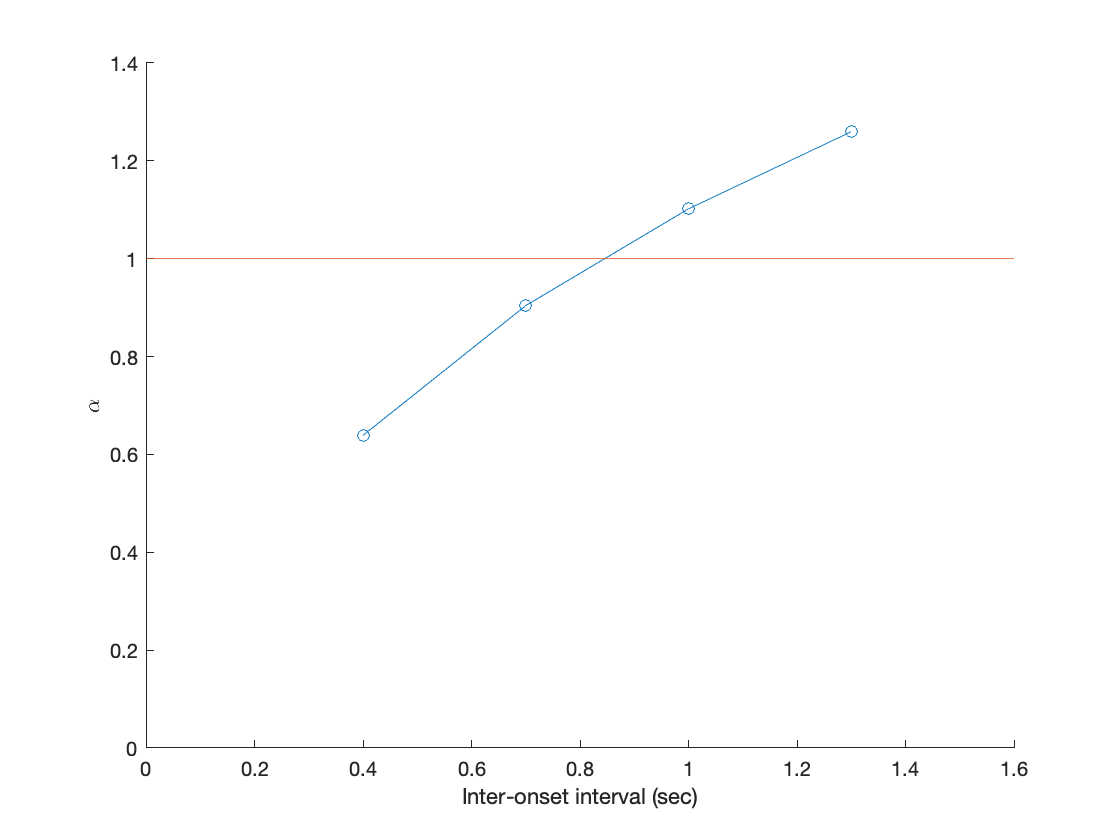

%ylim([3.9, 4])


figure()
hold on
plot(period_list, alpha_list, 'o-')
plot([0,1.6], [1,1], '-')
ylabel('\alpha')
xlabel('Inter-onset interval (sec)')
xlim([0, 1.6])
ylim([0, 1.4])

## Exploring tempo changes

true_tempo = 1;
period = 1/true_tempo;
delta = 0.05;

ET = period:period:9*period;
ET_speed = ET;
ET_slow = ET;

ET_speed(3:end)=ET_speed(3) + (0 : period - delta: 6*(period - delta));
ET_slow(3:end)=ET_slow(3) + (0 : period + delta: 6*(period + delta));

lu = .005;
hei = ones(size(ET));
hei(4) = 2;

sigma_theta = .01;
sigma_phi = .02;

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles',10,...
    'expected_period', 1,...
    'tau_unit',lu,...
    'sigma_phi', sigma_phi,...
    'sigma_theta', sigma_theta,...
    'true_speed', true_tempo,...
    'event_times', ET_speed,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, true_tempo],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Sped up',...
    'highlight_event_indices',hei,...
    'display_phase', true,...
    'display_tempo', true,...    
    'display_phasetempo', false);
[xbar_list_speed, Sigma_list_speed] = run_PATIPPET(params);

params = PATIPPET_params(...
    'means_unit', [1],...
    'expected_cycles',10,...
    'expected_period', 1,...
    'tau_unit',lu,...
    'sigma_phi', sigma_phi,...
    'sigma_theta', sigma_theta,...
    'true_speed', true_tempo,...
    'event_times', ET_slow,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, true_tempo],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', .0001,...
    'dt_ellipse',.25,...
    'title', 'Slowed down',...
    'highlight_event_indices',hei,...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[xbar_list_slow, Sigma_list_slow] = run_PATIPPET(params);

antitap_slow_list = [];
asynSigma_slow = [];
for i=2:size(xbar_list_slow, 2);
    if floor(xbar_list_slow(1, i) -.5)>floor(xbar_list_slow(1, i-1) -.5)
        antitap_slow_list(end+1) = i*params.dt;
        asynSigma_slow(end+1) = i*params.dt + .5/xbar_list_slow(2, i) - ET_slow(length(antitap_slow_list));
    end
end
ITI_slow = diff(antitap_slow_list)

antitap_speed_list = [];
asynSigma_speed = [];
for i=2:size(xbar_list_speed, 2);
    if floor(xbar_list_speed(1, i) -.5)>floor(xbar_list_speed(1, i-1) -.5)
        antitap_speed_list(end+1) = i*params.dt;
        asynSigma_speed(end+1) = i*params.dt + .5/xbar_list_speed(2, i) - ET_speed(length(antitap_speed_list));
    end
end
ITI_speed = diff(antitap_speed_list)

figure()
hold on
plot(asynSigma_slow, 'ob')
plot(asynSigma_speed, 'or')
plot([0, length(ITI_slow)], [0,0])
%plot([0, length(ITI_speed)], (period-delta)*[1,1])


## Comparing PATIPPET with and without theta correction

In second draft of manuscript, equations were updated such that events occurred dphi rather than dt -- thus, the rate of events within a given measure is the same regardless of tempo. One result was that tempo could be estimated from event rate when the event rate was constant. Here is PATIPPET's behavior with and without this correction.

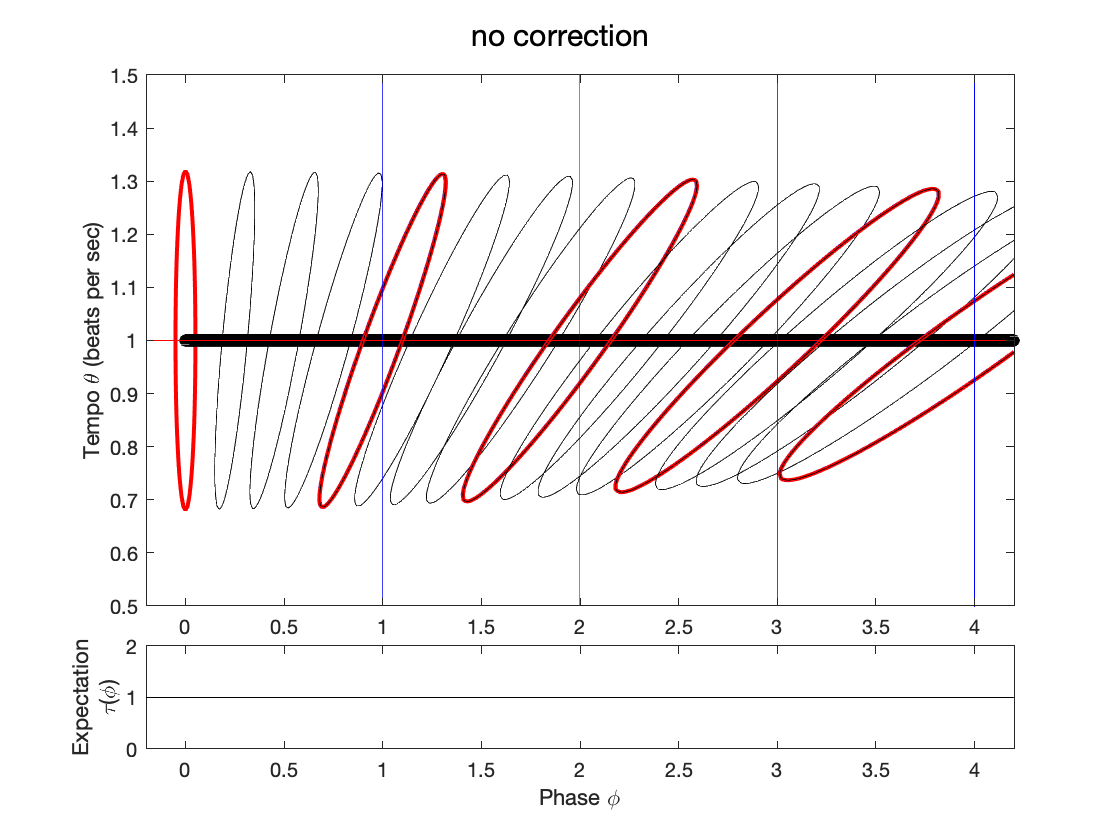




params = PATIPPET_params(...
    'means_unit', [1],...
    'tau_unit', [0],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, 1],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', 1,...
    'dt_ellipse',.25,...
    'corrected', false,...
    'title', 'no correction');
[xbar_list, Sigma_list] = run_PATIPPET(params);

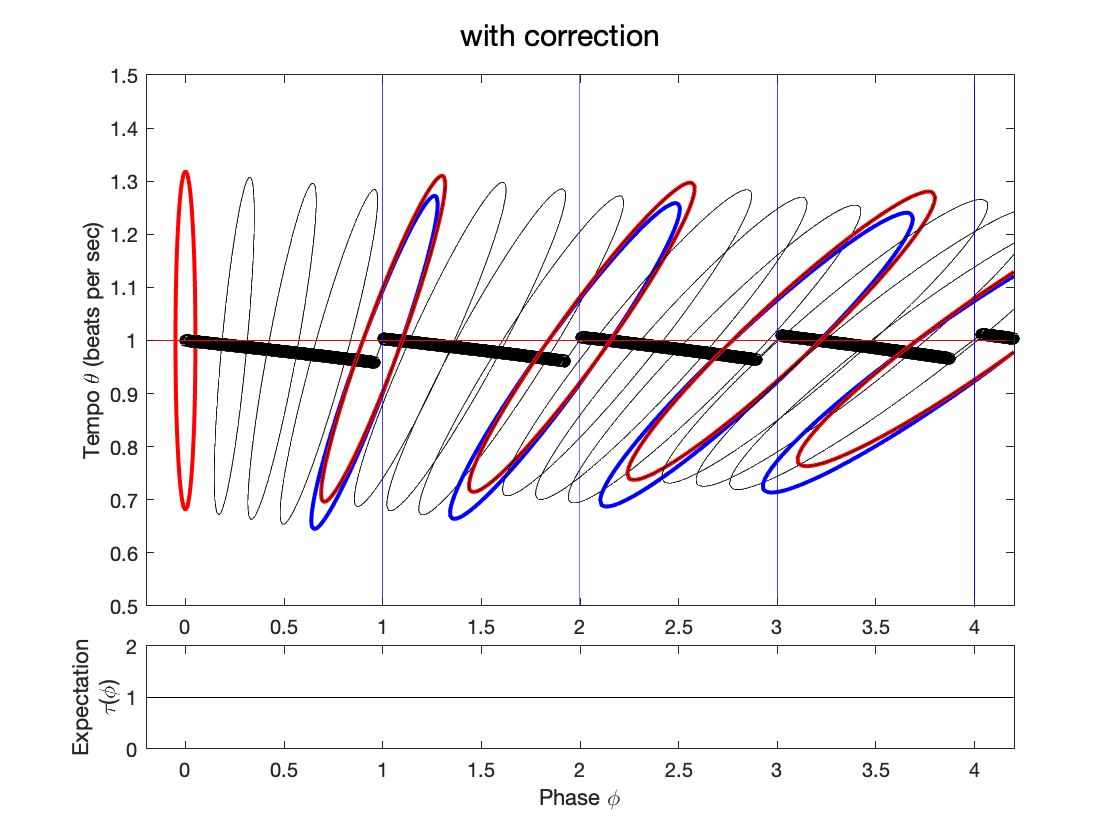


params = PATIPPET_params(...
    'means_unit', [1],...
    'tau_unit', [0],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'event_times', period:period:4*period,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, 1],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', 1,...
    'dt_ellipse',.25,...
    'corrected', true,...
    'title', 'with correction');
[xbar_list, Sigma_list] = run_PATIPPET(params);

## Keith Doelling's task

true_tempo = 1.2;
period = 1/true_tempo;
cycles = 6;

event_times = period:period:cycles*period;
event_times = event_times + .1*randn(size(event_times));

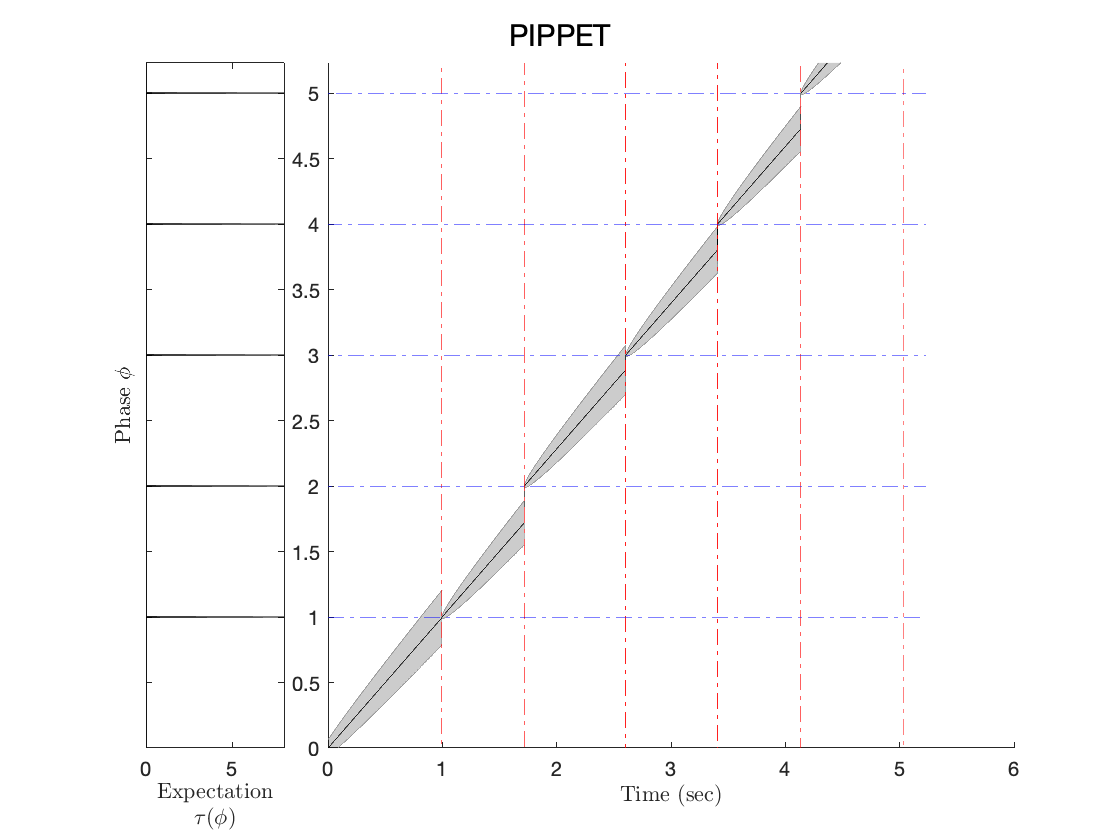

params = PIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.000001],...
    'expected_cycles', 8,...
    'expected_period', 1,...%'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'phibar_0', 0,...%[0, 1],...
    'V_0', [.001],...%,0; 0,.04],...
    'tau_0', 0,...
    'sigma_phi',.1,...%'sigma_2',0.001,...
    'title', 'PIPPET'...
    );
[xbar_list, Sigma_list] = run_PIPPET(params);

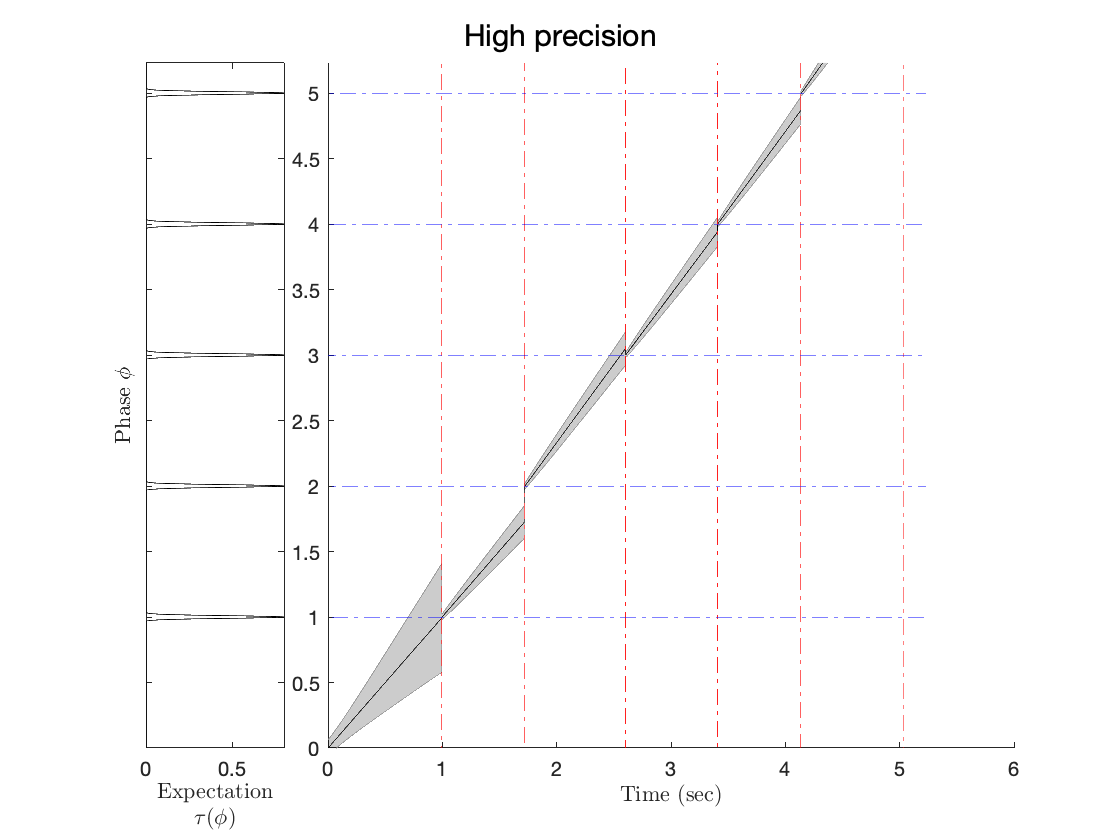

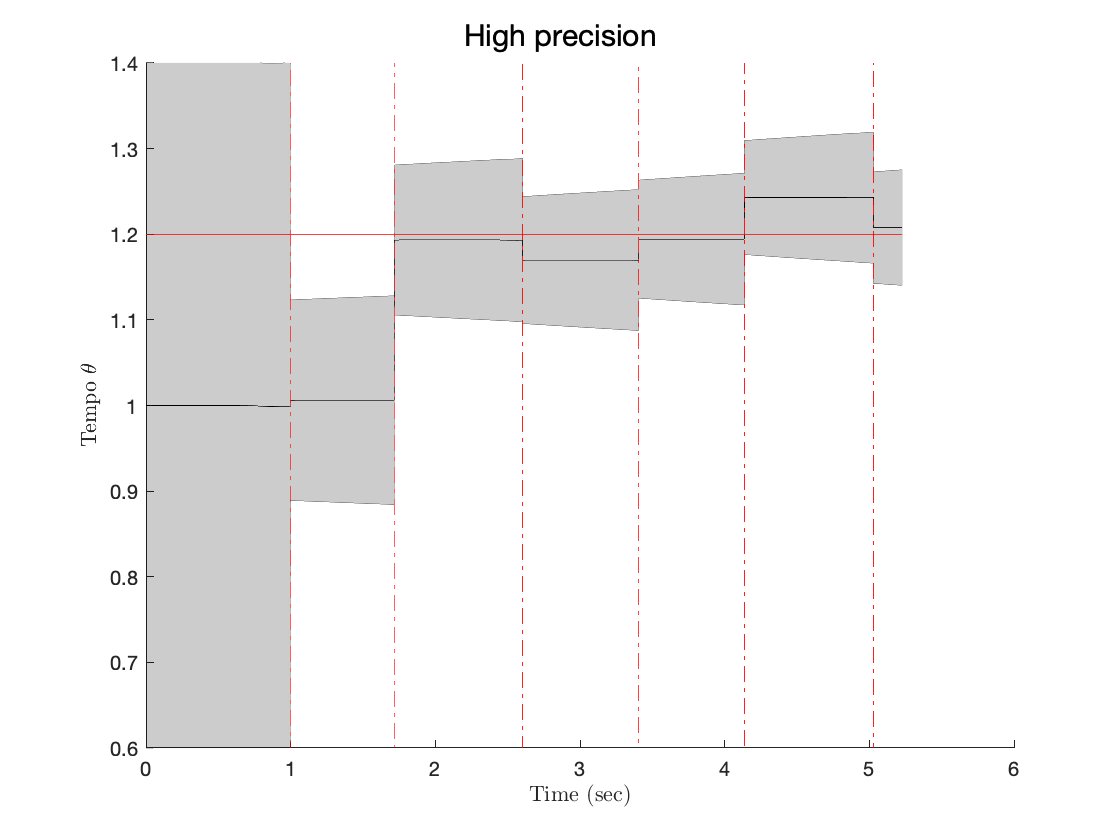


params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.0001],...
    'expected_cycles', cycles,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, 1],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', 0,...
    'sigma_phi',0.05,...
    'sigma_theta',0.02,...
    'title', 'High precision', ...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[xbar_list, Sigma_list] = run_PATIPPET(params);

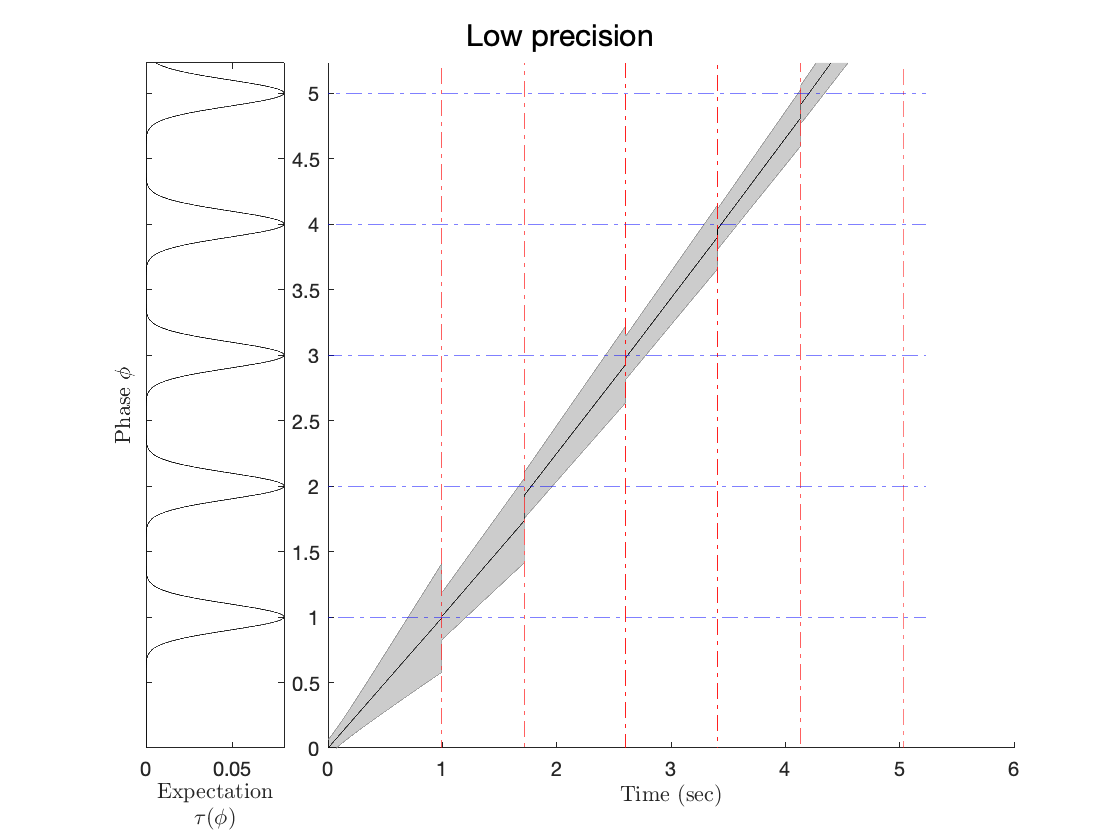

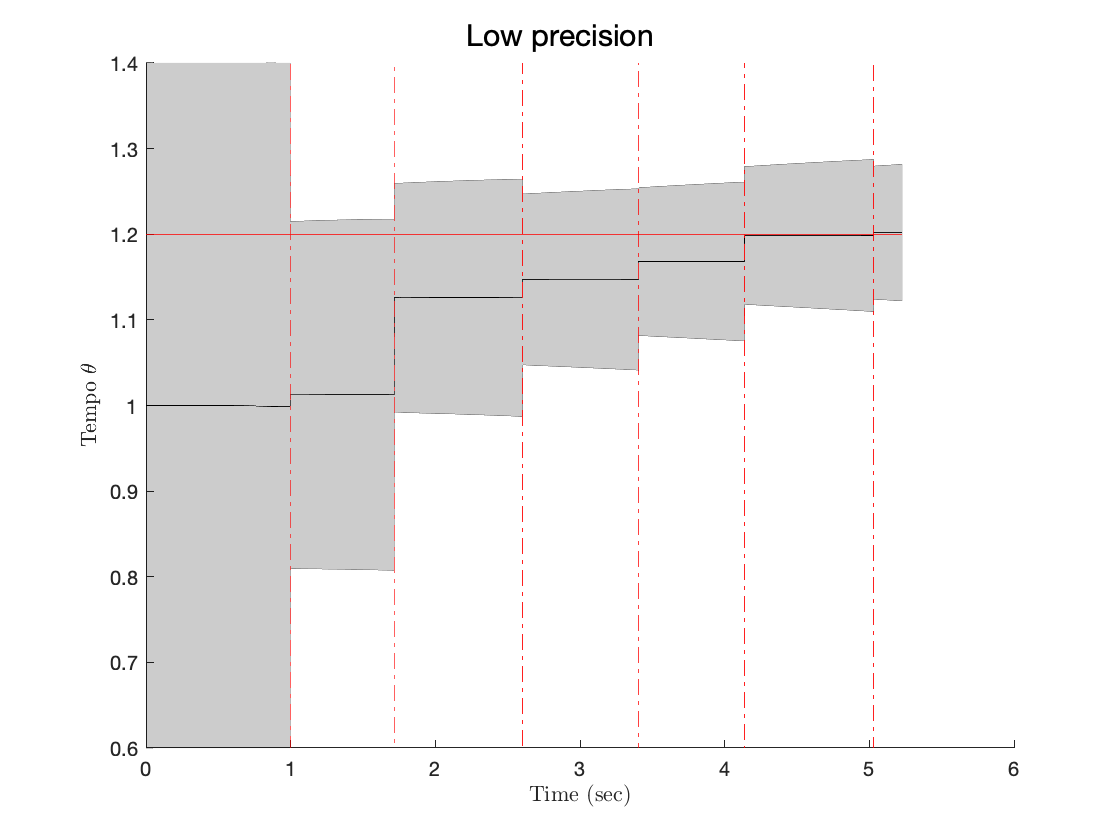


params = PATIPPET_params(...
    'means_unit', [1],...
    'variance_unit',[.01],...
    'expected_cycles', cycles,...
    'expected_period', 1,...
    'true_speed', true_tempo,...
    'event_times', event_times,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'xbar_0', [0, 1],...
    'Sigma_0', [.001,0; 0,.04],...
    'tau_0', 0,...
    'sigma_phi',0.05,...
    'sigma_theta',0.02,...
    'title', 'Low precision', ...
    'display_phase', true,...
    'display_tempo', true,...   
    'display_phasetempo', false);
[xbar_list, Sigma_list] = run_PATIPPET(params);